# IOPID/FOPD max period estimating template

This is a template for estimating largest sampling period of IOPID/FOPD controller. Change the controller_type to meet your needs. From now on, We only need to maintain this script rather than two scripts. 

## Computing for FOPD or  IOPID

tic
clc;clear;
array_size=512;
controller_type='FOPD';
comment='par';
h=linspace(0.1,10,array_size); %
omega=zeros(length(h),1);
f_h=zeros(length(h),1);
parpool(16);

Starting parallel pool (parpool) using the 'local' profile ...
connected to 16 workers.


parfor n=1:array_size
    fprintf('\n====Adding time stamps:%s====\n',...
        datestr(now,'yyyy/mm/dd-HH:MM:SS.FFF'));
    fprintf('Step: %d/%d\n',n,array_size);
    fprintf('Calling sub-layer function.');
%     [ omega(n),f_h(n) ]=cal_f_h(h(n));
    [ omega(n),f_h(n) ]=...
        cal_f_h_selector(h(n),controller_type);
    fprintf('Displaying results for: %s',controller_type);
    disp(['h=' num2str(h(n))]);
    disp(['f_h=' num2str(f_h(n))]);
end


====Adding time stamps:2018/10/25-16:03:25.486====

====Adding time stamps:2018/10/25-16:03:25.507====

====Adding time stamps:2018/10/25-16:03:25.496====

====Adding time stamps:2018/10/25-16:03:25.499====

====Adding time stamps:2018/10/25-16:03:25.523====

====Adding time stamps:2018/10/25-16:03:25.489====

====Adding time stamps:2018/10/25-16:03:25.543====

====Adding time stamps:2018/10/25-16:03:25.499====

====Adding time stamps:2018/10/25-16:03:25.519====

====Adding time stamps:2018/10/25-16:03:25.495====

====Adding time stamps:2018/10/25-16:03:25.497====

====Adding time stamps:2018/10/25-16:03:25.536====

====Adding time stamps:2018/10/25-16:03:25.504====

====Adding time stamps:2018/10/25-16:03:25.498====

====Adding time stamps:2018/10/25-16:03:25.558====

====Adding time stamps:2018/10/25-16:03:25.523====
Step: 2/512
Step: 4/512
Step: 6/512
Step: 8/512
Step: 10/512
Step: 13/512
Step: 17/512
Step: 22/512
Step: 28/512
Step: 35/512
Step: 44/512
Step: 69/512
Step: 85/512
Ste

toc

Elapsed time is 248.075245 seconds.


## Saving data to file

datafilename=['f_h_' controller_type '_01_100_' comment ...
    num2str(array_size)];
save([datafilename '.mat']);
fprintf('Saved data file: %s', [datafilename '.mat']);

Saved data file: f_h_FOPD_01_100_par512.mat

## Loading saved FOPD data

load f_h_FOPD_01_100_par512

## Loading saved IOPID data

load f_h_IOPID_01_100_par512

## Plotting section

figure
plot(h,f_h,'-o');
xlabel('h');
ylabel('f(h)');
legend(controller_type);
saveas(gcf,[datafilename '.fig']);
saveas(gcf,[datafilename '.png']);

## Proving only one crosspoint

if controller_type == 'IOPID'
    axis([0 10 -5 5]);
elseif controller_type == 'FOPD'
    axis([0 10 -5 5]);
end
saveas(gcf,[datafilename 'cross.png']);
saveas(gcf,[datafilename 'cross.fig']);

## Estimating the crosspoint

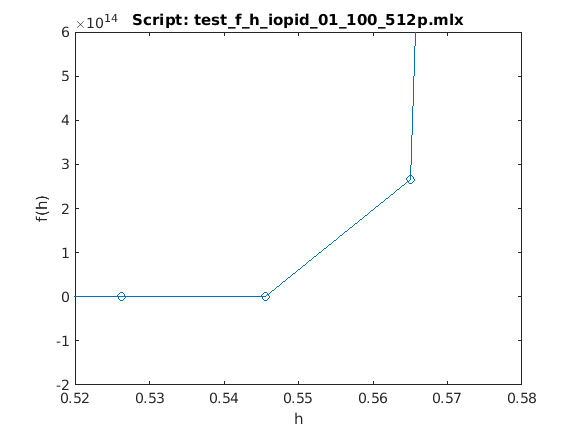

if controller_type == 'IOPID'
    axis([0.52 0.58 -2e14 6e14]);
elseif controller_type == 'FOPD'

    axis([0.52 0.58 -2e14 6e14]);
end

Figure saved.


Elapsed time is 269.044910 seconds.


saveas(gcf,[datafilename '_value.png']);
saveas(gcf,[datafilename '_value.fig']);
disp('Figure saved.')
